%Initialize vars

uTarg=5; %constraint of u part 2 and 3
H=60;
beta=2334.17;
alpha=25;

f=1.5

f = 1.5000

%compensator gain tuning part 3

%cnum0=0; part 1 numerator
%cdom0=0; part 1 denominator
cnum0=alpha; %part 2 & 3 comp numerator

%part 2 compensator alpha prime
%cdom0=sqrt((4.*uTarg.*beta)./H);

%part 3 comp alpha tuning
cdom0=35.5

cdom0 = 35.5000

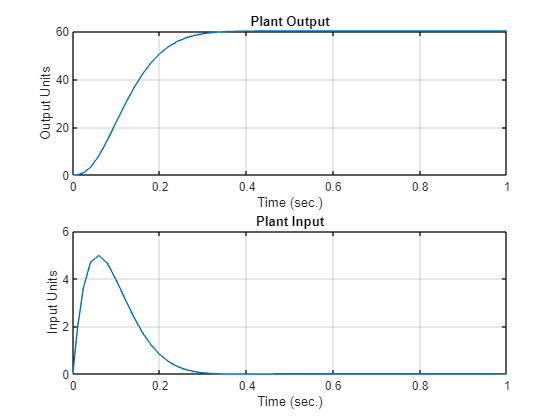

Ts = 0.3240

max_output = 60.0000

max_input = 4.9780


% K=(alpha.^2)./(4.*beta); Part 1 gain
%K=(cdom0.^2)./(4.*beta);  Part 2 gain

K=f.*(cdom0.^2)./(4.*beta); %part 3 gain
Kf=cdom0./2; %part3 filter

%update graphs
sim("HW1.slx",1);
waitfor(HW1);
run("graphs.m")

%optimizer cheats
%keywords for potential techniques:
%optimal control
%dead-beat control
%Fractional-order control
%Distributed parameter systems
%H-infinity loop shaping
%Servomechanism
%Control theory

